R = [14.7 14.8 14.6 15.1 15 15.2 15.1 14.5 14.9 14.6 14.8 15 14.9 15.2 14.8 15 15.1 15.1 14.7 14.6 14.8 14.9 14.5 15 14.8 15.1 15.2 14.5 15.1 14.9]

R =    14.7000   14.8000   14.6000   15.1000   15.0000   15.2000   15.1000   14.5000   14.9000   14.6000   14.8000   15.0000   14.9000   15.2000   14.8000   15.0000   15.1000   15.1000   14.7000   14.6000   14.8000   14.9000   14.5000   15.0000   14.8000   15.1000   15.2000   14.5000   15.1000   14.9000


fprintf("max = %.1f кОм, min = %.1f кОм, дельта = %.1f кОм", max(R), min(R), max(R) - min(R));

max = 15.2 кОм, min = 14.5 кОм, дельта = 0.7 кОм

[N, sv, do, Xj, mj, xj, xmj, xxmj, X0, shag] = foo(R);

shag = 0.1200

(max(R) - min(R))/6

ans = 0.1167

for i = 1:1:6
    fprintf("%d | %.2f | %.2f | %.2f | %d <-|  %.f   %.f  %.f\n", N(i), sv(i), do(i), Xj(i), mj(i), xj(i), xmj(i), xxmj(i));
    fprintf("--+-------+-------+-------+--------------")
end % Важно проверить колонку с m

1 | 14.48 | 14.60 | 14.54 | 6 <-|  -3   -18  54


--+-------+-------+-------+--------------

2 | 14.60 | 14.72 | 14.66 | 2 <-|  -2   -4  8


--+-------+-------+-------+--------------

3 | 14.72 | 14.84 | 14.78 | 5 <-|  -1   -5  5


--+-------+-------+-------+--------------

4 | 14.84 | 14.96 | 14.90 | 4 <-|  0   0  0


--+-------+-------+-------+--------------

5 | 14.96 | 15.08 | 15.02 | 4 <-|  1   4  4


--+-------+-------+-------+--------------

6 | 15.08 | 15.20 | 15.14 | 9 <-|  2   18  36


--+-------+-------+-------+--------------

fprintf("X_0 = %.2f кОм       delta_X = %.2f кОм", X0, shag);

X_0 = 14.90 кОм       delta_X = 0.12 кОм

ai1 = 0

ai1 = 0

for i = 1:1:6
    ai1 = ai1 + xmj(i)
end

ai1 = -18.0000

ai1 = -22.0000

ai1 = -27.0000

ai1 = -27.0000

ai1 = -23.0000

ai1 = -5.0000

ai1 = ai1/6;
ai2 = 0;
for i = 1:1:6
    ai2 = ai2 + xxmj(i);
end
ai2 = ai2/30;
fprintf("a_i1 = %.4f            a_i2 = %.4f ", ai1, ai2);

a_i1 = -0.8333            a_i2 = 3.5667 

fprintf("X| = %f           S = %f",X0 +ai1*shag, shag*sqrt(ai2 - ai1^2));

X| = 14.800000           S = 0.203372

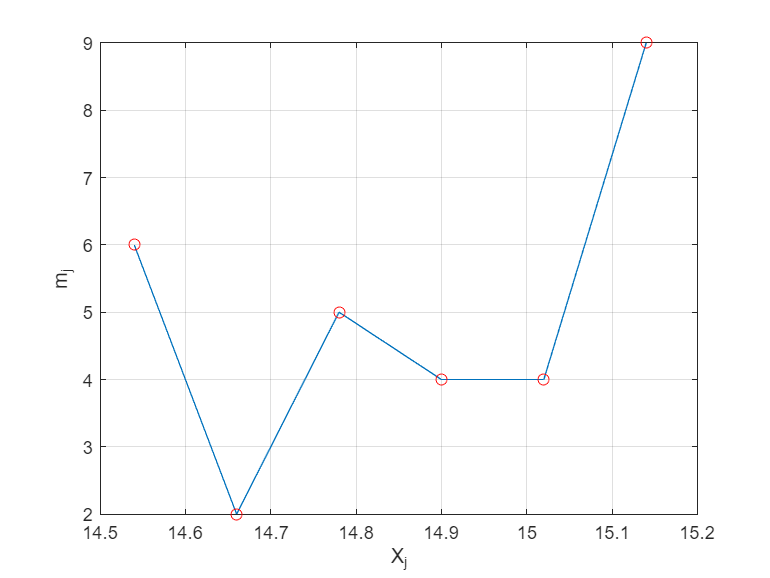

plot(Xj, mj);
hold on;
plot(Xj, mj, ['o', 'r']);
grid on;
xlabel("X_j");
ylabel("m_j");

function [N, sv, do, Xj, mj, xj, xmj, xxmj, X0, shag] = foo(R)
    N = [1 2 3 4 5 6];
    shag = 0.12 %(max(R) - min(R))/6;
    sv = zeros(1, 6);
    do = zeros(1, 6);
    sv(6) = max(R) - shag; do(6) = max(R);
    for i = 5:-1:1
        sv(i) = sv(i + 1) - shag;
        do(i) = do(i + 1) - shag;
    end
    Xj = zeros(1, 6);
    for i = 1:1:6
        Xj(i) = (sv(i) + do(i))/2;
    end
    Ysl = 4; % условное значение
    mj = zeros(1, 6);
    for i = 1:1:6
        for j = 1:1:30
            if (R(j) >= sv(i)) && (R(j) <= do(i))
                mj(i) = mj(i) + 1;
            end
        end
    end
    xj = zeros(1, 6);
    X0 = Xj(Ysl);
    for i = 1:1:6
        xj(i) = (Xj(i) - X0)/shag;
    end
    xmj = xj.*mj;
    xxmj = xj.*xmj;
end